## Read sequence

chromosome_of_interest = 'chr2';

chromosome_of_interest = 'chr2'

tic
filename = strcat("Human Genome/", chromosome_of_interest, "_shorter.txt")

filename = "Human Genome/chr2_shorter.txt"

f = fopen(filename,'rt');
chrm_sequence = fgetl(f);
toc

Elapsed time is 8.055689 seconds.


L = length(chrm_sequence)

L = 11000000

fclose(f);

chrm_sequence = string(chrm_sequence)

chrm_sequence = "NNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNNN

### Get the PWM for a particular TF

TF_of_interest = 'CTCF';

f = fopen('factorbookMotifPwm.txt','rt');
thisline = fgetl(f);
pwm_matrix = [];
TF_binding_length = 0;
while true
    if ~ischar(thisline); break; end  %end of file
    C = strsplit(thisline,"\t");
    
    TF = C(1,1);
    TF = string(TF{1});
    if TF == TF_of_interest
        TF_binding_length = C(1,2);
        TF_binding_length = TF_binding_length{1};
        TF_binding_length = str2double(TF_binding_length);
        for i=3:6
            row = C(1,i);
            row = string(row{1});
            row = strsplit(row,",");
            pwm_matrix = [pwm_matrix; str2double(row(1:TF_binding_length))];
        end
        break;
    end
    thisline = fgetl(f);
end
pwm_matrix = pwm_matrix + 0.01

pwm_matrix =     0.0640    0.0340    0.0780    0.0520    0.0100    0.2720    0.0140    0.0100    0.0420    0.2760    0.0300    0.0900    0.0200    0.0360    0.1360
    0.3280    0.6560    0.0520    0.8000    1.0040    0.6760    0.6280    1.0080    0.0740    0.1000    0.3540    0.2040    0.0120    0.0760    0.6040
    0.5760    0.0340    0.8020    0.0720    0.0100    0.0560    0.0120    0.0120    0.0180    0.5740    0.6300    0.0540    0.9860    0.8500    0.0840
    0.0720    0.3160    0.1080    0.1160    0.0160    0.0360    0.3860    0.0100    0.9060    0.0900    0.0260    0.6920    0.0220    0.0780    0.2160


pwm_matrix = log(pwm_matrix)

pwm_matrix =    -2.7489   -3.3814   -2.5510   -2.9565   -4.6052   -1.3020   -4.2687   -4.6052   -3.1701   -1.2874   -3.5066   -2.4079   -3.9120   -3.3242   -1.9951
   -1.1147   -0.4216   -2.9565   -0.2231    0.0040   -0.3916   -0.4652    0.0080   -2.6037   -2.3026   -1.0385   -1.5896   -4.4228   -2.5770   -0.5042
   -0.5516   -3.3814   -0.2206   -2.6311   -4.6052   -2.8824   -4.4228   -4.4228   -4.0174   -0.5551   -0.4620   -2.9188   -0.0141   -0.1625   -2.4769
   -2.6311   -1.1520   -2.2256   -2.1542   -4.1352   -3.3242   -0.9519   -4.6052   -0.0987   -2.4079   -3.6497   -0.3682   -3.8167   -2.5510   -1.5325


TF_binding_length

TF_binding_length = 15

fclose(f);

## Get TF Binding Positions if not already saved

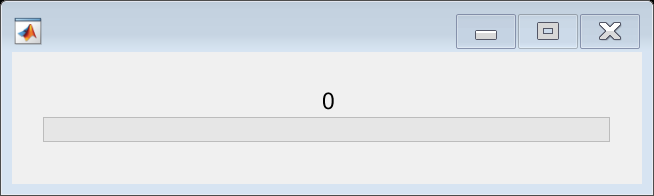

C1 = 1×3 cell array
    {'       11475'}    {'        11496'}    {'        UAK25            -'}


Index in position 2 exceeds array bounds (must not exceed 3).

TF_binding_pos = [];
TF_pos_filename = strcat('factor_pos_separated/', chromosome_of_interest, '_TF_pos.txt');
TFbinding_sites_file = fopen(TF_pos_filename,'rt');

% Regulatory regions 
reg_file_name = strcat("RegTfbs/", chromosome_of_interest, "_regTfbs.txt");
regulatory_regions_file = fopen(reg_file_name,'rt');

thisline_TF = fgetl(TFbinding_sites_file);
thisline_TF = fgetl(TFbinding_sites_file);
thisline_Reg = fgetl(regulatory_regions_file);
thisline_Reg = fgetl(regulatory_regions_file);

x = 0; % number of regulatory regions covered
loading = waitbar(0,'Please wait...');
while x < 278
    r = x/278;
    progress = round(r,2);
    waitbar(progress,loading,string(progress));
    if ~ischar(thisline_TF); break; end  %end of file
    
    if ~ischar(thisline_Reg); break; end  %end of file
    
    C1 = strsplit(thisline_TF,"\t")
    C2 = strsplit(thisline_Reg,"\t");
    strand = C1(1,4);
    strand = strand{1};

    start1 = C1(1,1);
    stop1 = C1(1,2);
    name = C1(1,3);
    name = name{1};
    
    if string(name) ~= TF_of_interest
        thisline_TF = fgetl(TFbinding_sites_file);
        continue;
    end

    start2 = C2(1,1);
    stop2 = C2(1,2);
    site_id = C2(1,3);
    site_id = site_id{1};
    
    site_id_arr = strsplit(site_id,".");
    site_id_num = site_id_arr(1,2);
    site_id_num = str2double(site_id_num{1});

    start1 = str2double(start1{1});
    start2 = str2double(start2{1});
    stop1 = str2double(stop1{1});
    stop2 = str2double(stop2{1});
    
    if start2 > start1
        thisline_TF = fgetl(TFbinding_sites_file);
    elseif start1 > stop2
        thisline_Reg = fgetl(regulatory_regions_file);
        x = x + 1;
    elseif start1 > start2 && stop1 < stop2
        if string(strand) == '+'
            TF_binding_pos = [TF_binding_pos; site_id_num, start1 , start2, 1]
        else
            TF_binding_pos = [TF_binding_pos; site_id_num, start1 , start2, 0]
        end
        

        thisline_TF = fgetl(TFbinding_sites_file);
    else
        thisline_TF = fgetl(TFbinding_sites_file);
        thisline_Reg = fgetl(regulatory_regions_file);
        x = x + 1;
    end
end

TF_binding_pos


save_name = strcat(TF_of_interest, '_binding_positions')
save(save_name, "TF_binding_pos")


load_name = strcat(TF_of_interest, '_binding_positions')
load(load_name, "TF_binding_pos")

my_own_TWM =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


## Get Actual Positions

actual_positions = [];

## Calculate My Own TWM to confirm accuracy of positions

nukes = {'A', 'C', 'G', 'T'};
my_own_TWM_row = repmat([0], 1, TF_binding_length);
my_own_TWM = repmat(my_own_TWM_row, 4, 1)

reg_file_name = "RegTfbs/chr2_regTfbs.txt"

## Calculate Minimum Score of a binding region for a particular TF.

scores = [];
% TF binding sites
TF_pos_filename = strcat('factor_pos_separated/', chromosome_of_interest, '_TF_pos.txt');
TFbinding_sites_file = fopen(TF_pos_filename,'rt');
% Regulatory regions 
reg_file_name = strcat("RegTfbs/", chromosome_of_interest, "_regTfbs.txt")
regulatory_regions_file = fopen(reg_file_name,'rt');

thisline_TF = fgetl(TFbinding_sites_file);
thisline_Reg = fgetl(regulatory_regions_file);
thisline_Reg = fgetl(regulatory_regions_file);

x = 0; % number of regulatory regions covered
loading = waitbar(0,'Please wait...');
while x < 278
    r = x/278;
    progress = round(r,2);
    waitbar(progress,loading,string(progress));
    if ~ischar(thisline_TF); break; end  %end of file
    
    if ~ischar(thisline_Reg); break; end  %end of file
    
    C1 = strsplit(thisline_TF,"\t");
    C2 = strsplit(thisline_Reg,"\t");
    strand = C1(1,7);
    strand = strand{1};

    start1 = C1(1,3);
    stop1 = C1(1,4);
    name = C1(1,5);
    name = name{1};
    
    if string(name) ~= TF_of_interest
        thisline_TF = fgetl(TFbinding_sites_file);
        continue;
    end

    start2 = C2(1,1);
    stop2 = C2(1,2);
    site_id = C2(1,3);
    site_id = site_id{1};
    
    site_id_arr = strsplit(site_id,".");
    site_id_num = site_id_arr(1,2);
    site_id_num = str2double(site_id_num{1});

    start1 = str2double(start1{1});
    start2 = str2double(start2{1});
    stop1 = str2double(stop1{1});
    stop2 = str2double(stop2{1});
    if start2 > start1
        thisline_TF = fgetl(TFbinding_sites_file);
    elseif start1 > stop2
        thisline_Reg = fgetl(regulatory_regions_file);
        x = x + 1;
    elseif start1 > start2 && stop1 < stop2
        if string(strand) == '+'
            for k = 1:TF_binding_length
                r = extractBetween(chrm_sequence,start1+k,start1+k);
                pos = find(nukes == r);
                my_own_TWM(pos, k) = my_own_TWM(pos, k) + 1;
            end
            r = extractBetween(chrm_sequence,start1+1,start1+TF_binding_length);
            score =  get_score(0, r, pwm_matrix, TF_binding_length, 1);
            scores = [scores; score];
            actual_positions = [actual_positions; site_id_num, start1+1, 1, ceil(score)];
        else 
            for k = 1:TF_binding_length
                r = extractBetween(chrm_sequence,start1+k,start1+k);
                pos = find(nukes == r);
                my_own_TWM(5-pos, TF_binding_length-k+1) = my_own_TWM(5-pos, TF_binding_length-k+1) + 1;
            end
            r = extractBetween(chrm_sequence,start1+1,start1+TF_binding_length);
            score = get_score(0, r, pwm_matrix, TF_binding_length, 0);
            scores = [scores; score];
            actual_positions = [actual_positions; site_id_num, start1+1, 0, ceil(score)];
        end

        thisline_TF = fgetl(TFbinding_sites_file);

Error using waitbar (line 103)
The second argument must be a message character vector or a handle to an existing waitbar.

    else
        thisline_TF = fgetl(TFbinding_sites_file);
        thisline_Reg = fgetl(regulatory_regions_file);
        x = x + 1;
    end
end
fclose(TFbinding_sites_file);
fclose(regulatory_regions_file);
close(loading)
x
h = histogram(scores)
min(scores)
mean(scores)
std(scores)
mean(scores) - std(scores)

dif =     0.2187    0.1578    0.2956    0.0489    0.4545    0.1925    0.4505    0.4545    0.1498    0.0067    0.1618    0.1927    0.2627    0.7922    0.2376
   -0.1362   -0.4642    0.2307   -0.5173   -0.7213   -0.5751   -0.2544   -0.6344    0.2087    0.0918   -0.2531   -0.0122    0.2707   -0.0660   -0.3213
   -0.3842    0.3396   -0.6102    0.1198    0.1818    0.1358    0.1798    0.0889    0.2647   -0.2913   -0.3473    0.3196   -0.6124   -0.7491    0.1987
    0.3016   -0.0333    0.0838    0.3485    0.0849    0.2467   -0.3760    0.0909   -0.6233    0.1927    0.4385   -0.5002    0.0789    0.0229   -0.1151


my_own_TWM = my_own_TWM / length(actual_positions);

actual_positions =           17      714183           1         -34
          17      714273           0         -44
          21      856491           1         -40
          31     1821396           1         -31
          34     1891972           0         -40
          37     2105810           1         -36
          37     2105897           1         -30
          66     3606604           0         -28
         185     9516289           1         -33
         192     9714310           1         -40


my_own_TWM = my_own_TWM + 0.01;
my_own_TWM = log(my_own_TWM)
pwm_matrix

threshold = -15.2243

dif = exp(my_own_TWM) - exp(pwm_matrix)
actual_positions

## Predict Positions for PWM

threshold = min(scores)
regulatory_regions_file = fopen('RegTfbs/chr1_regTfbs.txt','rt');
thisline = fgetl(regulatory_regions_file);

positions = [];
for i = 1:480
    thisline = fgetl(regulatory_regions_file);
    C = strsplit(thisline,"\t");
    start = C(1,1);
    stop = C(1,2);
    start = str2double(start{1});
    stop = str2double(stop{1});
    site_id = C(1,3);
    site_id = site_id{1};
    
    site_id_arr = strsplit(site_id,".");
    site_id_num = site_id_arr(1,2);
    site_id_num = str2double(site_id_num{1});
    
    region = extractBetween(chrm_sequence,start,stop);
    region = region{1};
    L = length(region);

positions =            1      237750           1         -13
           1      237752           0         -10
           1      237762           0         -11
           2      521379           1         -14
           2      521533           1         -10
           2      521535           0          -9
           2      521545           0         -11
           3      714082           1         -14
           3      714183           1         -12
           3      714273           0         -11


    positions = [positions; get_positions(region, pwm_matrix, TF_binding_length, threshold, start, site_id_num)];

ans = 0.0039

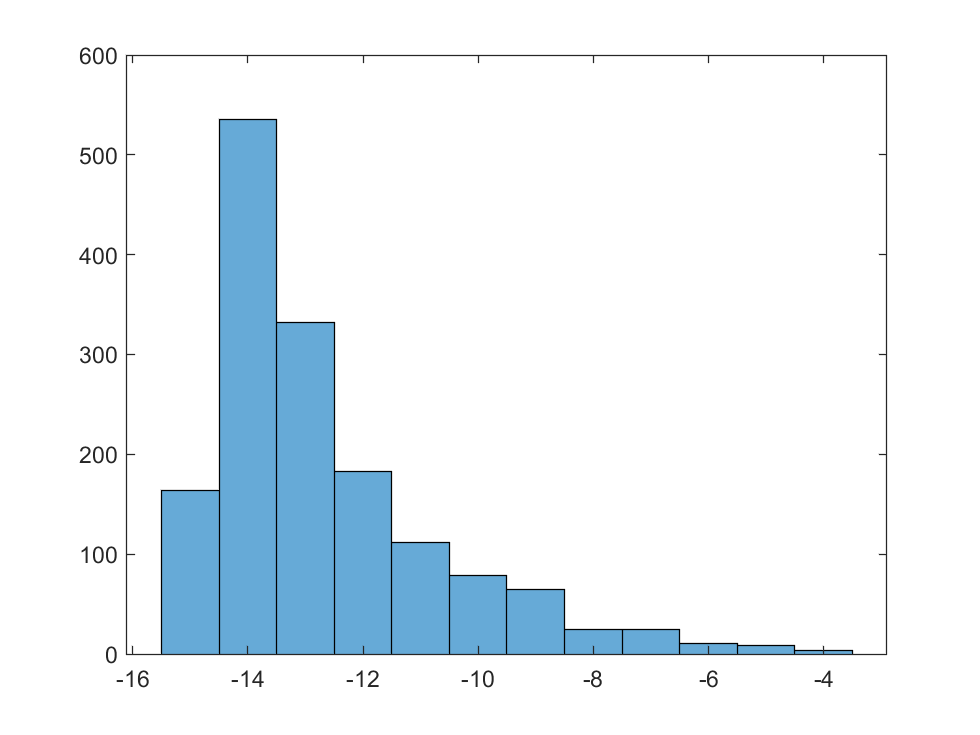

end

fclose(regulatory_regions_file);
positions
length(positions(:, 1)) / 391478
histogram(positions(:, 4))

## Found vs not found

found = 0;
success = false;
found_scores = [];
not_found_scores = [];

for i=1:length(actual_positions)
    for k=1:length(positions)
        if positions(k,2) == actual_positions(i, 2) && positions(k,3) == actual_positions(i, 3)
            found = found + 1;
            region = extractBetween(chrm_sequence,positions(k,2),positions(k,2) + TF_binding_length + 1);
            score = get_score(0, region, pwm_matrix, TF_binding_length, positions(k,3));
            found_scores = [found_scores; score];
            success= true;
            break; 
        end
    end
    if success == false
        false;
        region = extractBetween(chrm_sequence,actual_positions(i, 2),actual_positions(i, 2) + TF_binding_length + 1);
        score = get_score(0, region, pwm_matrix, TF_binding_length, actual_positions(i, 3));
        not_found_scores = [not_found_scores; score];
    end
    success = false;

ans = -12.1134

end

ans = 2.2099

mean(found_scores)

ans = -14.3234

std(found_scores)

ans = NaN

mean(found_scores) - std(found_scores)

ans = NaN

mean(not_found_scores)

ans = NaN

std(not_found_scores)

found = 746

mean(not_found_scores) - std(not_found_scores)

percentageFound = 1

found

ans = 0.4832

percentageFound = found / length(actual_positions)
found / length(positions(:, 1))

## Positive vs negative

positive = 0;
success = false;
positive_scores = [];
negative_scores = [];

merged_data = [];

for k=1:length(positions)
    for i=1:length(actual_positions)
        if positions(k,2) == actual_positions(i, 2) && positions(k, 3) == actual_positions(i, 3)
            positive = positive + 1;
            region = extractBetween(chrm_sequence,actual_positions(i, 2),actual_positions(i, 2) + TF_binding_length + 1);
            score = get_score(0, region, pwm_matrix, TF_binding_length, actual_positions(i, 3));
            if  actual_positions(i, 4) ~= positions(k, 4)
                error = '000'
                positions(k, 4)
                actual_positions(i, 4)
            end
            if  ceil(score) ~= positions(k, 4)
                error = 'first'
            end
            if  actual_positions(i, 4) ~= ceil(score)
                error = 'second'
                ceil(score)
                actual_positions(i, 4)
            end
            merged_data = [merged_data; actual_positions(i, :) 1];
            positive_scores = [positive_scores; ceil(score)];
            success= true;
            break; 
        end
    end
    if success == false
        false;
        region = extractBetween(chrm_sequence,positions(k, 2),positions(k, 2) + TF_binding_length + 1);
        score = get_score(0, region, pwm_matrix, TF_binding_length, positions(k, 3));
        negative_scores = [negative_scores; ceil(score)];
        merged_data = [merged_data; positions(k, :) 0];

        if  ceil(score) ~= positions(k, 4)
            error = 'third'
        end
    end
    success = false;
end

mean(positive_scores)

ans = -11.6005

std(positive_scores)

ans = 2.2288

mean(positive_scores) - std(positive_scores)

ans = -13.8294

mean(negative_scores)

ans = -13.6805

std(negative_scores)

ans = 1.1232

mean(negative_scores) - std(negative_scores)

ans = -14.8037

positive

positive = 746

percentagePositive = positive / length(positions)

percentagePositive = 0.4832

positive / length(actual_positions(:, 1))

ans = 1

merged_data

merged_data =            1      237750           1         -13           1
           1      237752           0         -10           1
           1      237762           0         -11           1
           2      521379           1         -14           0
           2      521533           1         -10           1
           2      521535           0          -9           1
           2      521545           0         -11           1
           3      714082           1         -14           0
           3      714183           1         -12           1
           3      714273           0         -11           1


## Save Data

save_name = strcat(TF_of_interest, '_positions')

save_name = 'CTCF_positions'

save(save_name, "merged_data")

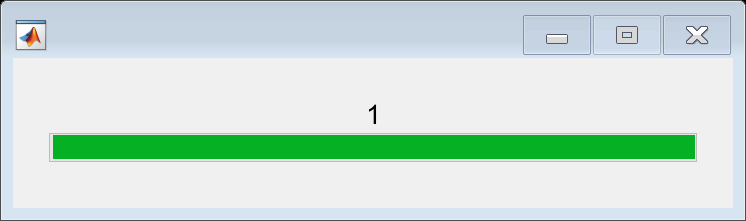


mapObj_TF = containers.Map({'initiate'}, {0});
mapRegions = containers.Map({'initiate'}, {0});

TFbinding_sites_file = fopen('factorbookMotifPos.txt','rt');

f = waitbar(0, 'Please wait...');
thisline1 = fgetl(TFbinding_sites_file);
for i = 1:1000
    r = i/1000;
    progress = round(r,2);
    waitbar(progress,f,string(progress));
    if ~ischar(thisline1); break; end  %end of file

    C = strsplit(thisline1,"\t");

    chromosome = C(1,2);

    strand = C(1,7);
    
    if string(chromosome{1}) ~= 'chr1'
        break;
    end
 
    
    start = C(1,3);
    stop = C(1,4);
    name = C(1,5);
    name = name{1};


    start = str2double(start{1});
    stop = str2double(stop{1});
    
    if mapObj_TF.isKey(name)
        mapObj_TF(name) = mapObj_TF(name) + 1;
    else
        mapObj_TF(name) = 1;
    end

    thisline1 = fgetl(TFbinding_sites_file);
end

TFnames = keys(mapObj_TF)

TFnames = 1×84 cell array
    {'AP1'}    {'AP2'}    {'BARHL2'}    {'BHLHE40'}    {'CEBPB'}    {'CREB'}    {'CREB-ext'}    {'CTCF'}    {'CTCF-ext'}    {'E2F1'}    {'E2F4'}    {'EBF1'}    {'EGR1'}    {'ELF'}    {'ELF1'}    {'ESR1'}    {'ETS1'}    {'FOXA'}    {'GABP'}    {'GATA1'}    {'GATA1-ext'}    {'GATA3'}    {'HNF4'}    {'MAX'}    {'MEF2'}    {'MYC'}    {'NFE2'}    {'NFIC'}    {'NFKB1'}    {'NFY'}    {'NR2C2'}    {'NR3C1'}    {'NRF1'}    {'PAX5'}    {'POU2F2'}    {'PRDM1'}    {'PU1'}    {'REST'}    {'RFX5'}    {'RUNX1'}    {'RXRA'}    {'SP1'}    {'STAT1'}    {'TAL1'}    {'TCF12'}    {'TCF3'}    {'TCF7L2'}    {'TEAD4'}    {'UA1'}    {'UA2'}    {'UA3'}    {'UA6'}    {'UA7'}    {'UA9'}    {'UAK17'}    {'UAK18'}    {'UAK21'}    {'UAK22'}    {'UAK25'}    {'UAK26'}    {'UAK27'}    {'UAK29'}    {'UAK30'}    {'UAK31'}    {'UAK35'}    {'UAK36'}    {'UAK40'}    {'UAK41'}    {'UAK42'}    {'UAK45'}    {'UAK48'}    {'UAK52'}    {'UAK57'}    {'UAK61'}    {'USF'}    {'YY1'}    {'ZEB1'}    {'ZNF143'


for x = 1:length(TFnames)
    name = cell2mat(TFnames(x))
    mapObj_TF(name)
end

name = 'AP1'

ans = 11

name = 'AP2'

ans = 10

name = 'BARHL2'

ans = 1

name = 'BHLHE40'

ans = 13

name = 'CEBPB'

ans = 5

name = 'CREB'

ans = 5

name = 'CREB-ext'

ans = 9

name = 'CTCF'

ans = 104

name = 'CTCF-ext'

ans = 13

name = 'E2F1'

ans = 15

name = 'E2F4'

ans = 76

name = 'EBF1'

ans = 14

name = 'EGR1'

ans = 86

name = 'ELF'

ans = 2

name = 'ELF1'

ans = 15

name = 'ESR1'

ans = 4

name = 'ETS1'

ans = 1

name = 'FOXA'

ans = 4

name = 'GABP'

ans = 11

name = 'GATA1'

ans = 1

name = 'GATA1-ext'

ans = 1

name = 'GATA3'

ans = 2

name = 'HNF4'

ans = 5

name = 'MAX'

ans = 15

name = 'MEF2'

ans = 3

name = 'MYC'

ans = 22

name = 'NFE2'

ans = 3

name = 'NFIC'

ans = 1

name = 'NFKB1'

ans = 7

name = 'NFY'

ans = 3

name = 'NR2C2'

ans = 2

name = 'NR3C1'

ans = 1

name = 'NRF1'

ans = 43

name = 'PAX5'

ans = 10

name = 'POU2F2'

ans = 1

name = 'PRDM1'

ans = 1

name = 'PU1'

ans = 1

name = 'REST'

ans = 2

name = 'RFX5'

ans = 4

name = 'RUNX1'

ans = 6

name = 'RXRA'

ans = 2

name = 'SP1'

ans = 51

name = 'STAT1'

ans = 2

name = 'TAL1'

ans = 2

name = 'TCF12'

ans = 3

name = 'TCF3'

ans = 5

name = 'TCF7L2'

ans = 2

name = 'TEAD4'

ans = 2

name = 'UA1'

ans = 10

name = 'UA2'

ans = 5

name = 'UA3'

ans = 40

name = 'UA6'

ans = 1

name = 'UA7'

ans = 1

name = 'UA9'

ans = 5

name = 'UAK17'

ans = 16

name = 'UAK18'

ans = 14

name = 'UAK21'

ans = 2

name = 'UAK22'

ans = 4

name = 'UAK25'

ans = 14

name = 'UAK26'

ans = 9

name = 'UAK27'

ans = 9

name = 'UAK29'

ans = 6

name = 'UAK30'

ans = 4

name = 'UAK31'

ans = 3

name = 'UAK35'

ans = 2

name = 'UAK36'

ans = 2

name = 'UAK40'

ans = 1

name = 'UAK41'

ans = 1

name = 'UAK42'

ans = 89

name = 'UAK45'

ans = 2

name = 'UAK48'

ans = 2

name = 'UAK52'

ans = 4

name = 'UAK57'

ans = 5

name = 'UAK61'

ans = 8

name = 'USF'

ans = 15

name = 'YY1'

ans = 13

name = 'ZEB1'

ans = 3

name = 'ZNF143'

ans = 6

name = 'ZNF143-ext'

ans = 5

name = 'ZNF263'

ans = 69

name = 'ZNF281'

ans = 12

name = 'initiate'

ans = 0

name = 'v-JUN'

ans = 11

name = 'v-Maf'

ans = 5

mapObj_TF(TF_of_interest)

ans = 11

regions = keys(mapRegions)

regions = 1×1 cell array
    {'initiate'}


% for x = 1:length(regions)
%     name = cell2mat(regions(x))
%     mapRegions(name)
% end
fclose(TFbinding_sites_file);

chrm_name = "chr1"

ans = 0.0000 + 1.0000i

chrm_name = "chr2"

ans = 0.0000 + 1.0000i

chrm_name = "chr3"

ans = 0.0000 + 1.0000i

chrm_name = "chr4"

ans = 0.0000 + 1.0000i

chrm_name = "chr5"

ans = 0.0000 + 1.0000i

chrm_name = "chr6"

ans = 0.0000 + 1.0000i

chrm_name = "chr7"

ans = 0.0000 + 1.0000i

chrm_name = "chr8"

ans = 0.0000 + 1.0000i

chrm_name = "chr9"

ans = 0.0000 + 1.0000i

chrm_name = "chr10"

ans = 0.0000 + 1.0000i

chrm_name = "chr11"

ans = 0.0000 + 1.0000i

chrm_name = "chr12"

ans = 0.0000 + 1.0000i

chrm_name = "chr13"

ans = 0.0000 + 1.0000i

chrm_name = "chr14"

ans = 0.0000 + 1.0000i

chrm_name = "chr15"

ans = 0.0000 + 1.0000i

chrm_name = "chr16"

ans = 0.0000 + 1.0000i

chrm_name = "chr17"

ans = 0.0000 + 1.0000i

chrm_name = "chr18"

ans = 0.0000 + 1.0000i

chrm_name = "chr19"

ans = 0.0000 + 1.0000i

chrm_name = "chr20"

ans = 0.0000 + 1.0000i

chrm_name = "chr21"

ans = 0.0000 + 1.0000i

chrm_name = "chr22"

Elapsed time is 0.866794 seconds.


### This is some kind of crazy text file that contains info about DNA?? 

#### I think this is where the machine learning for shape comes from

fid = fopen('collection.txt','rt');
thisline = jsondecode(fgetl(fid))
% Interfaces
interfaces = thisline.interfaces.models

% DNA
    % chains
    % nucleotides
dna = thisline.dna
chains = thisline.dna.chains
nucs = thisline.dna.nucleotides
interfaces = thisline.interfaces.models
meta_data = thisline.meta_data
fclose(fid);

f = fopen('collection.txt','rt');
for i=1:10
  thisline = fgetl(f);
  if ~ischar(thisline); break; end  %end of file
    %now check whether the string in thisline is a "word", and store it if it is.
    %then
end
fclose(f);
